## v0 Intro

In this scrip i try to process experiment data, delete z, and make an average between x and y data, save as new processed_data.

## Loading data

figure
data_name='p47_5s'

data_name = 'p47_5s'

experiment_interval=5

experiment_interval = 5

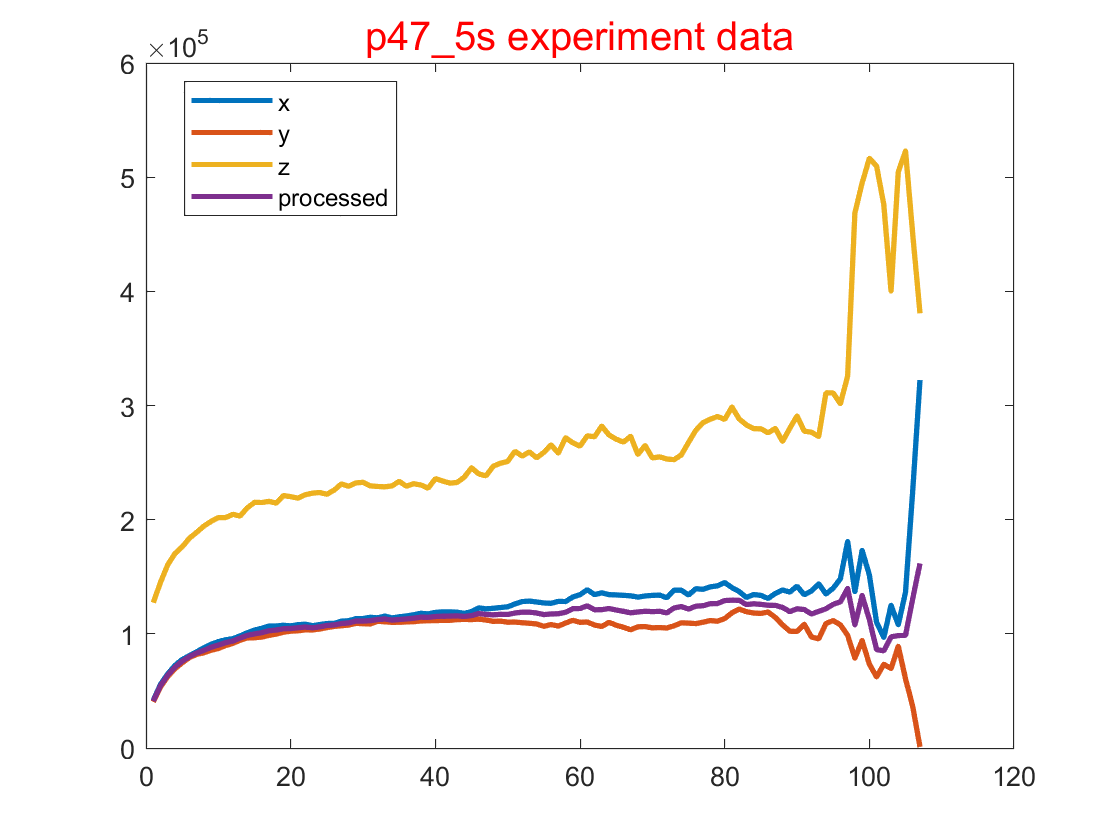

load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_',data_name,'_All.mat'])
plot(eval(['MSD_',data_name,'_All']).MSD_PP,'LineWidth',2)

hold on
processed_MSD=(eval(['MSD_',data_name,'_All']).MSD_PP(:,1)+eval(['MSD_',data_name,'_All']).MSD_PP(:,2))/2;
plot(processed_MSD,'LineWidth',2)
legend('x','y','z','processed','Location',"best");
%title(['p47\_5s experiment data'],'Fontsize',15,"Color",'r');
title(['p47\_5s experiment data'],'Fontsize',15,"Color",'r');


reserved_length=40;


## Saving part

saving_location='C:\Users\zhouquan\OneDrive\research\scrips\processed_data';
%save([saving_location,'\processed data ',data_name],'processed_MSD',"reserved_length")